clc,clear,close all
load result.mat

data = train4;

[sequences, labels] = dataLoader(data, 3);
function [sequences, labels] = dataLoader(data, window_size)
    windows = window_size;
    outputs = data(1,:);
    targets = data(2,:);
    labels = zeros([length(outputs)-windows, 1]);
    for j = windows+1:length(outputs)
        sequences{j-windows} = outputs(j-windows:j); 
        labels(j-windows) = targets(j);
    end 
end
RMSE=sqrt(mean((data(3,:)).^2))

RMSE = single
0.0711

train = sequences';
targets = labels ;

## model define

Output_size = 1;
Input_size = 1;
numHiddenUnits = 512; 
layers = [ ...
    sequenceInputLayer(Input_size)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    dropoutLayer(0.5)
    fullyConnectedLayer(50)
    reluLayer
    fullyConnectedLayer(Output_size)
    regressionLayer];


options = trainingOptions('adam', ...
    'MaxEpochs',500, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',100, ...
    'LearnRateDropFactor',0.2, ...
    'GradientThreshold',1, ...
    'Verbose',0);

net = trainNetwork(train,targets,layers,options);
pred = predict(net, train);
Error = abs(pred-targets);
RMSE=sqrt(mean((Error).^2))

RMSE = single
0.0456

MAE=mean(abs(Error))

MAE = single
0.0374

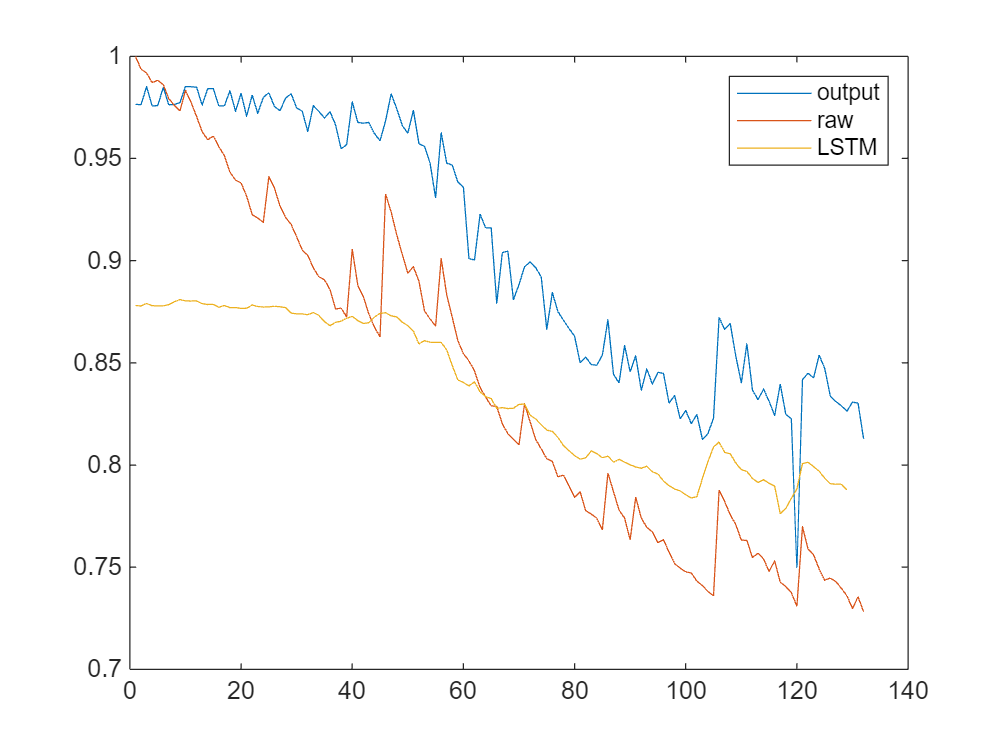

figure(1)
plot(data(1,:))
hold on 
plot(data(2,:))
hold on
plot(pred)
legend('output','raw','LSTM')
hold off


figure(3)
plot(data(2,:),data(1,:),'*')
hold on
raw = data(2,:)

raw = 1×132 single row vector
    1.0000    0.9937    0.9919    0.9872    0.9883    0.9861    0.9792    0.9761    0.9732    0.9834    0.9775    0.9705    0.9631    0.9592    0.9609    0.9558    0.9514    0.9434    0.9394    0.9380    0.9316    0.9225    0.9209    0.9188    0.9411    0.9356    0.9267    0.9212    0.9177    0.9117    0.9052    0.9026    0.8965    0.8921    0.8907    0.8859    0.8763    0.8768    0.8724    0.9057    0.8880    0.8824    0.8739    0.8675    0.8627    0.9325    0.9238    0.9127    0.9031    0.8939


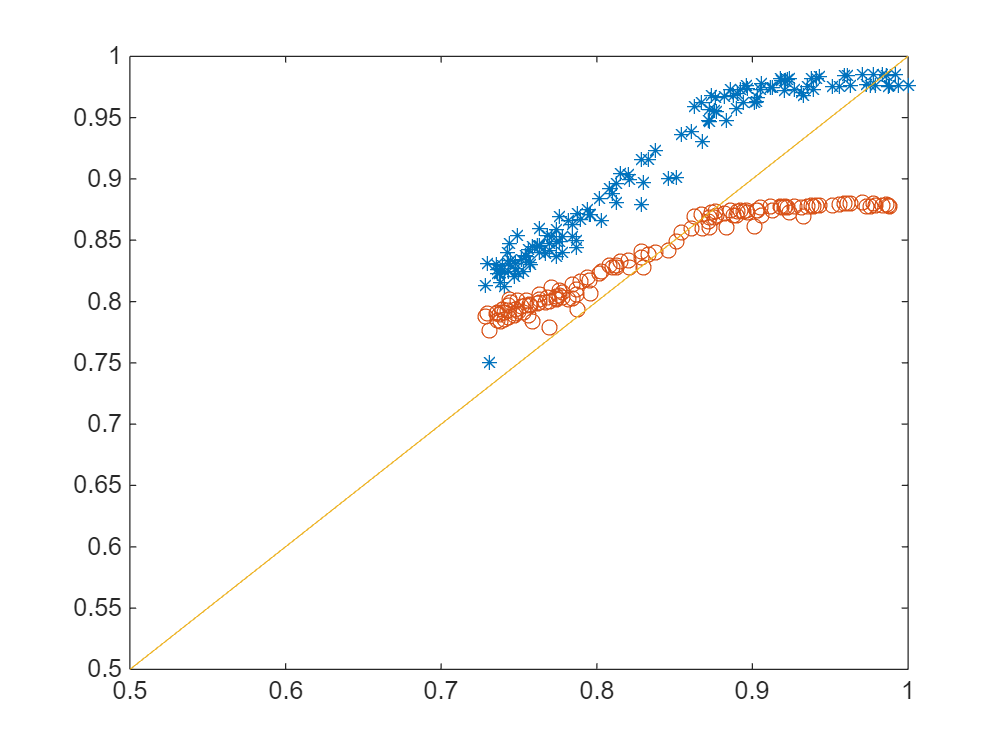

plot(raw(1,3+1:end),pred','o')
hold on
line([0.5,1],[0.5,1])

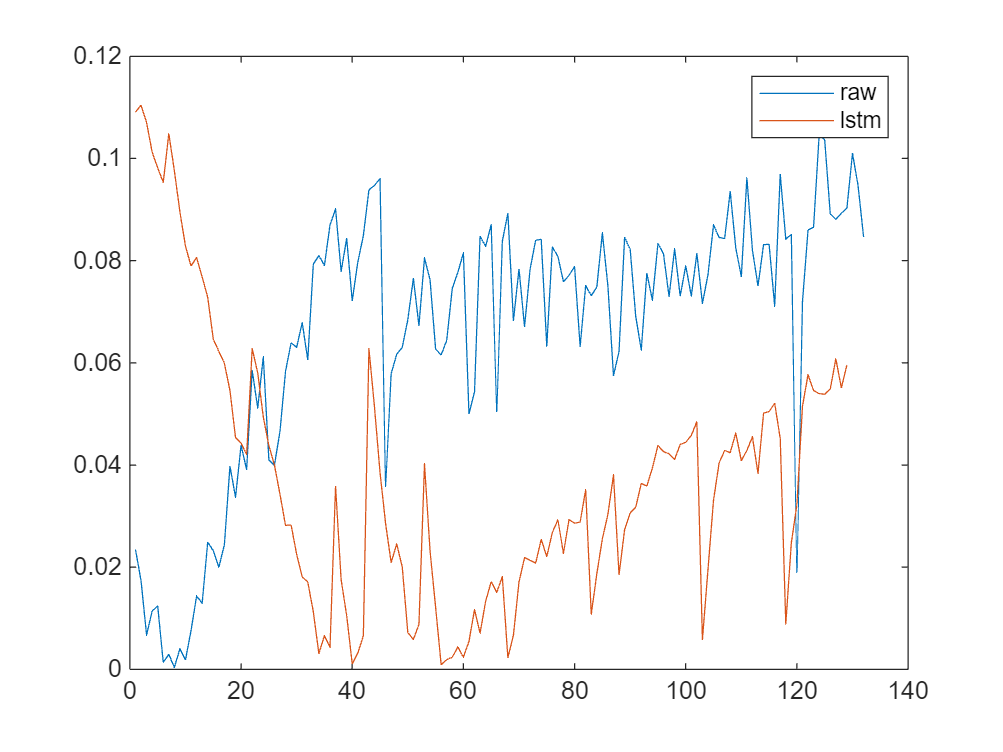





figure(2)
plot(abs(data(3,:)))
hold on
plot(abs(pred-targets))
legend('raw','lstm')